Make the mesh (Just simple linspace arrays).

xN=100;
L=1;
Tf=1;
xspan=linspace(0,L,xN);
tspan=linspace(0,Tf,100);
b=1;

Using the pdepe solver

nsol=pdepe(0,@heat1D,@ic,@bc,xspan,tspan);

Plotting the 3D representation of the time evolution of the 1D heat distribution.

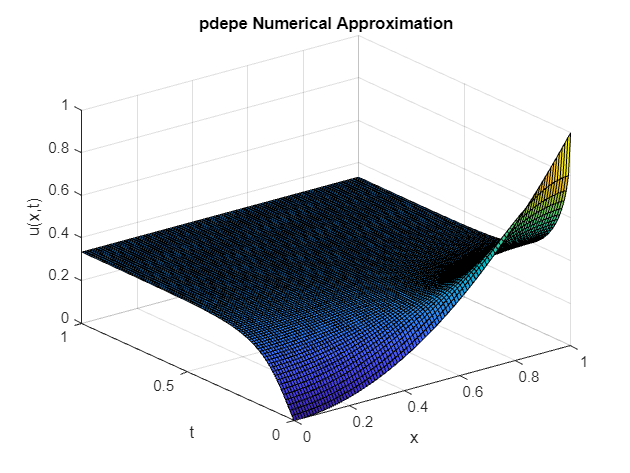

surf(xspan,tspan,nsol)
xlabel("x")
ylabel("t")
zlabel("u(x,t)")
title("pdepe Numerical Approximation")

Solving the PDE analytically using seperation of variables gives a cosine fourier series after applying the Neumann boundary conditions dudx=0 at the ends. When applying the initial conditions, we express x^2 as a cosine fourier series which gives the solution as:


$$u(x,t)=\frac{L^2}{3}+\sum_{n=1}^{\infty}(-1)^n\frac{4L^2}{\pi^2n^2}\cos\left(\frac{n\pi x}{L}\right)e^{-\left(\frac{n\pi}{L}\right)^2t}$$


We will analyse the change in computational efficiency and mean absolute error when the number of fourier terms are changed in the approximation. The function will be evaluated at all points used in the mesh. We will then calculate a matrix of absolute differences and see it's average difference. The computational efficiency will be seen by the CPU runtime graph.

First we define the symbolic variables used for the symbolic sum and the inputs for the symbolic function for the fourier expansion. We also define the maximum k used in the for loop. The number of expansions used are k+1. 

syms x t n
kMax=6;

We will make two empty arrays to carry the absolute mean differences and the time taken to compute the series. 

FourierandMATLABdifference=zeros(1,kMax+1);
timetaken=zeros(1,kMax+1);

A mesh grid is prepared over which the function will be evaluated.

[X,T]=meshgrid(xspan,tspan);

The main for loop which iterates over the log-2 of number fourier terms (k) starts here.

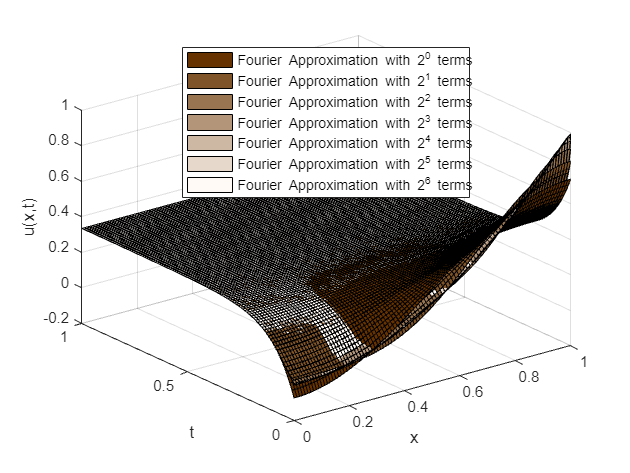

for k=0:kMax
    timeStart=cputime; %CPU timer starts here% 
    u(x,t)=L^2/3+symsum((-1)^n*4*L^2/(pi^2*n^2)*cos(n*pi*x/L)*exp(-(n*pi/L)^2*t),n,1,2^k);
    fouriersol=double(u(X,T));
    diff=abs(fouriersol-nsol);
    FourierandMATLABdifference(k+1)=mean(diff,"all");
    timetaken(k+1)=cputime-timeStart; %CPU timer stops here%
    surf(xspan,tspan,fouriersol,'FaceColor',[0.4+0.1*k 0.2+0.13*k 0.16*k],'DisplayName',"Fourier Approximation with 2^"+k+" terms")
    hold on
    xlabel("x")
    ylabel("t")
    zlabel("u(x,t)")
    drawnow;
end
legend('Location','north')
hold off

A log-2 plot is done for the time taken and the absolute mean difference between the PDE matlab toolbox and each fourier expansion.

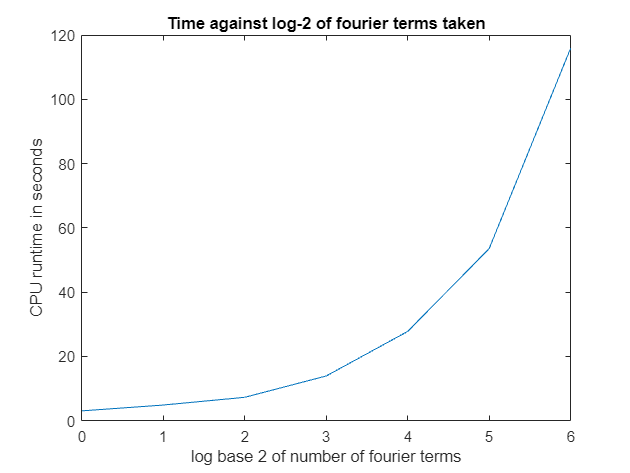

plot(0:kMax,timetaken)
title("Time against log-2 of fourier terms taken")
ylabel("CPU runtime in seconds")
xlabel("log base 2 of number of fourier terms")

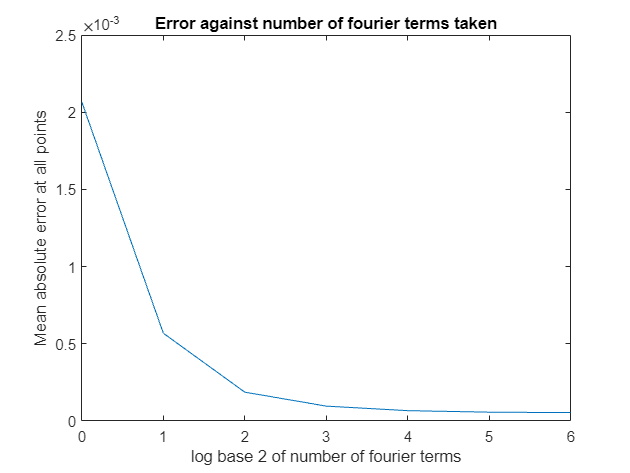

plot(0:kMax,FourierandMATLABdifference)
title("Error against number of fourier terms taken")
ylabel("Mean absolute error at all points")
xlabel("log base 2 of number of fourier terms")

Let's try the finite difference method:

We will use first the following explicit scheme for the 1D heat flow: $\frac{\partial u}{\partial t}=\beta\frac{\partial^2u}{\partial x^2}$


$$u_{i,j+1}=u_{i,j}\left(1-2\frac{\beta \Delta t}{(\Delta x)^2}\right)+\frac{\beta\Delta t}{(\Delta x)^2}\left(u_{i+1,j}+u_{i-1,j}\right)$$


Using Von Neumann analysis and ensuring that $|p|\le1$shows that the scheme is stable when $\frac{\beta \Delta t}{(\Delta x)^2}\le\frac12$.

We setup the number of iterations that will be done and make empty arrays to store the average absolute mean difference, CPU time taken, and $\frac{\beta \Delta t}{(\Delta x)^2}$.

mMax=7;
ExplicitandMATLABdifference=zeros(1,mMax);
timetakenE=zeros(1,mMax);
StabilityIndicator=zeros(1,mMax);

We start the main for loop over the different number of time steps here where it changes as a geometric sequence with ratio 2. The CPU timer is also started here.

for m=1:mMax
    timeStart=cputime; %CPU timer starts here%
    tN=9800*2^m;
    dt=Tf/tN;
    dx=L/(xN-1);
    StabilityIndicator(m)=b*dt/(dx)^2; %Scheme is stable when this number is less than or equal to 0.5%

Neumann boundary conditions $\left(\frac{\partial u}{\partial x}(0,t)=\frac{\partial u}{\partial x}(L,t)=0\right)$applied using a forward difference for the last index and a backward difference for the first index forces us to make two imaginary steps at index 1 and end.

    temp=zeros(tN,xN+2);

Initial condition is set as $u(x,0)=x^2$.

    for i=2:xN+1
        temp(1,i)=((i-2)*dx)^2;
    end

The first index is always equal to the second, and the last index is always equal to the one before last.

    temp(1,1)=temp(1,2);
    temp(1,end)=temp(1,end-1);

Now we will apply the scheme over all the xs at each time step.

    for j=2:tN
        for i=2:xN+1
           temp(j,i)=temp(j-1,i)*(1-2*b*dt/dx^2)+(b*dt/dx^2)*(temp(j-1,i+1)+temp(j-1,i-1));
        end
        temp(j,1)=temp(j,2);
        temp(j,end)=temp(j,end-1);
    end

We now remove the imaginary indices and resize the matrix such that it can be compared with the MATLAB toolbox solution. The timer is then stopped after the average absolute mean difference is calculated.

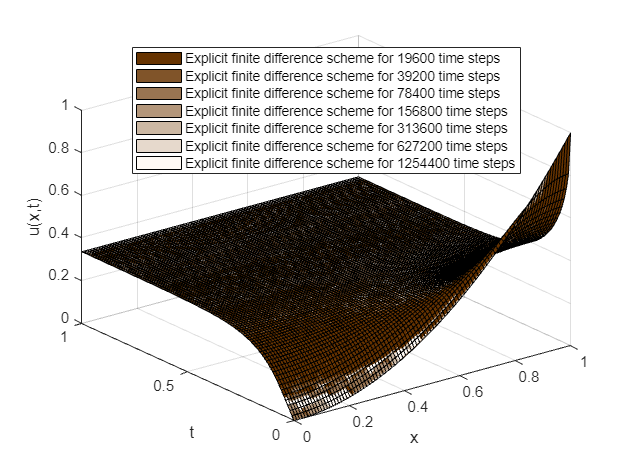

    modtemp=temp(:,2:101);
    te=linspace(0,Tf,tN);
    resizer=floor(linspace(1,tN,100));
    resizedmodtemp=modtemp(resizer,:);
    ExplicitandMATLABdifference(m)=mean(abs(resizedmodtemp-nsol),"all");
    timetakenE(m)=cputime-timeStart; %CPU timer stops here%
    surf(xspan,te(resizer),resizedmodtemp,'FaceColor',[0.4+0.1*(m-1) 0.2+0.13*(m-1) 0.16*(m-1)],'DisplayName',"Explicit finite difference scheme for "+tN+" time steps")
    hold on
    xlabel("x")
    ylabel("t")
    zlabel("u(x,t)")
    drawnow;
end
legend('Location','north')
hold off

A log-2 plot is done for the time taken and the absolute mean difference between the PDE matlab toolbox and each explicit finite difference scheme with different number of time steps.

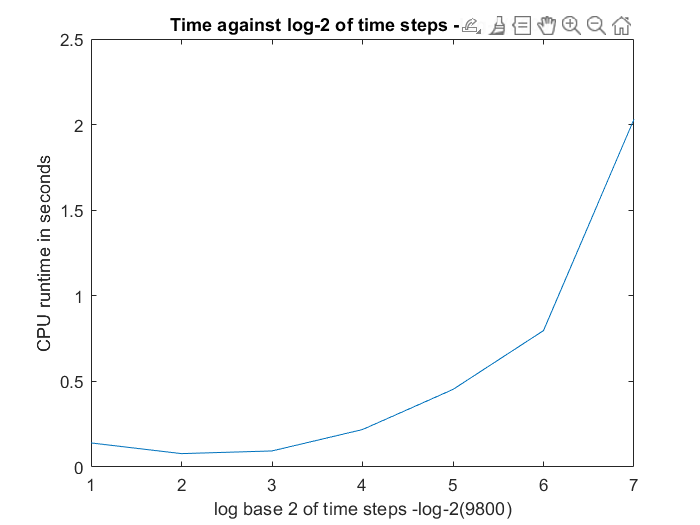

plot(timetakenE)
uicontrol("Visible","off")
title("Time against log-2 of time steps -log-2(9800)")
ylabel("CPU runtime in seconds")
xlabel("log base 2 of time steps -log-2(9800)")

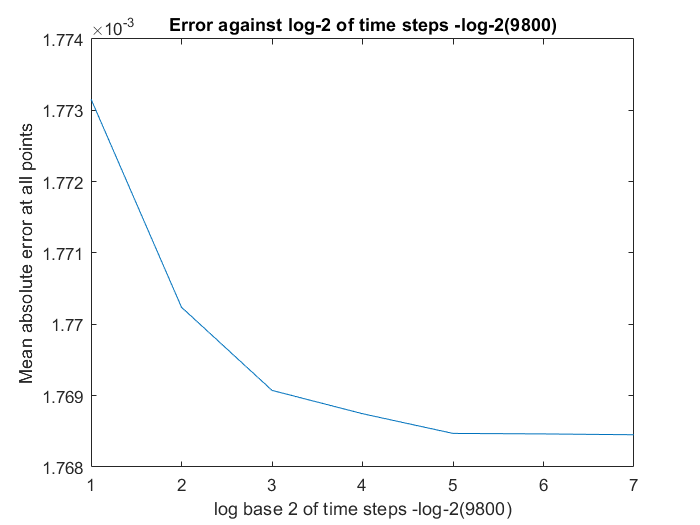

plot(ExplicitandMATLABdifference)
title("Error against log-2 of time steps -log-2(9800)")
ylabel("Mean absolute error at all points")
xlabel("log base 2 of time steps -log-2(9800)")

StabilityIndicator

StabilityIndicator =     0.5001    0.2500    0.1250    0.0625    0.0313    0.0156    0.0078


Changing the number of time steps barely affects the error, this is since the scheme has already achieved stability.

We will now change the number of time steps so that the scheme is unstable and observe the results.

pMax=45;
ExplicitUnstableandMATLABdifference=zeros(1,pMax);
timetakenEUnstable=zeros(1,pMax);
unStabilityIndicator=zeros(1,pMax);

We start the main for loop over the different number of time steps here where it changes as a arithemtic sequence starting from 19220 and adds 10 every iteration. The CPU timer is also started here.

for p=1:pMax
    timeStart=cputime; %CPU timer starts here%
    tN=19210+10*p;
    dt=Tf/tN;
    unStabilityIndicator(p)=b*dt/(dx)^2; %Scheme is stable when this number is less than or equal to 0.5%

Neumann boundary conditions $\left(\frac{\partial u}{\partial x}(0,t)=\frac{\partial u}{\partial x}(L,t)=0\right)$applied using a forward difference for the last index and a backward difference for the first index forces us to make two imaginary steps at index 1 and end.

    temp=zeros(tN,xN+2);

Initial condition is set as $u(x,0)=x^2$.

    for i=2:xN+1
        temp(1,i)=((i-2)*dx)^2;
    end

The first index is always equal to the second, and the last index is always equal to the one before last.

    temp(1,1)=temp(1,2);
    temp(1,end)=temp(1,end-1);

Now we will apply the scheme over all the xs at each time step.

    for j=2:tN
        for i=2:xN+1
           temp(j,i)=temp(j-1,i)*(1-2*b*dt/dx^2)+(b*dt/dx^2)*(temp(j-1,i+1)+temp(j-1,i-1));
        end
        temp(j,1)=temp(j,2);
        temp(j,end)=temp(j,end-1);
    end

We now remove the imaginary indices and resize the matrix such that it can be compared with the MATLAB toolbox solution. The timer is then stopped after the average absolute mean difference is calculated.

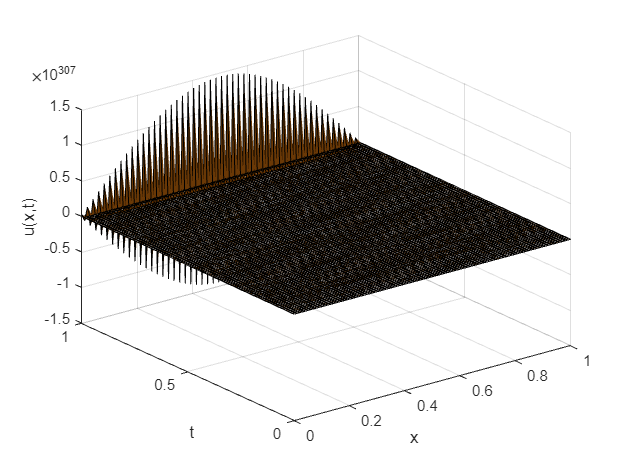

    modtemp=temp(:,2:101);
    te=linspace(0,Tf,tN);
    resizer=floor(linspace(1,tN,100));
    resizedmodtemp=modtemp(resizer,:);
    ExplicitUnstableandMATLABdifference(p)=mean(abs(resizedmodtemp-nsol),"all");
    timetakenEUnstable(p)=cputime-timeStart; %CPU timer stops here%
    surf(xspan,te(resizer),resizedmodtemp,'FaceColor',[0.4+0.0136*(p-1) 0.2+0.018*(p-1) 0.0227*(p-1)],'DisplayName',"Explicit finite difference scheme for "+tN+" time steps")
    hold on
    xlabel("x")
    ylabel("t")
    zlabel("u(x,t)")
    drawnow;
end
hold off

A log-2 plot is done for the time taken and the absolute mean difference between the PDE matlab toolbox and each explicit finite difference scheme with different number of time steps.

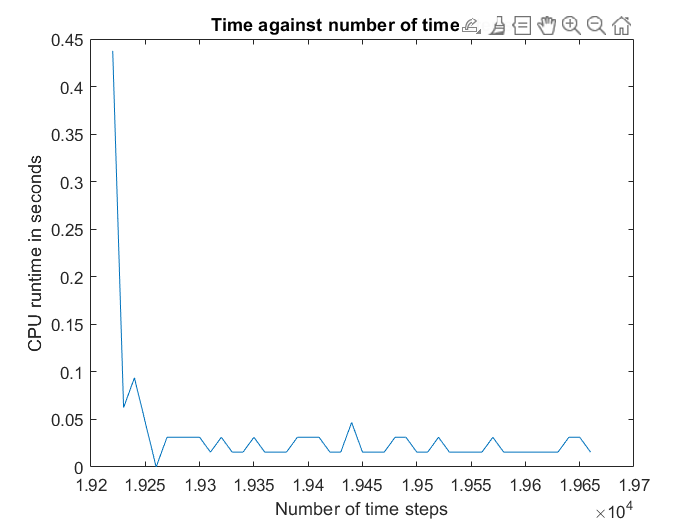

plot(19220:10:19660,timetakenEUnstable)
uicontrol("Visible","off")
title("Time against number of time steps")
ylabel("CPU runtime in seconds")
xlabel("Number of time steps")

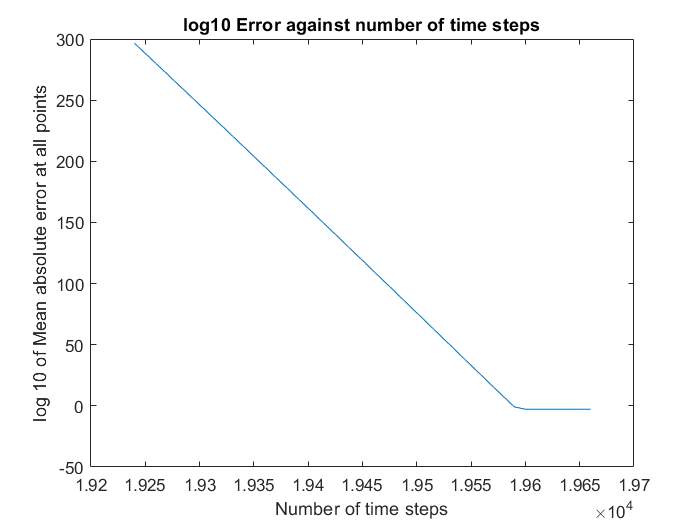

log10EUMd=log10(ExplicitUnstableandMATLABdifference);
plot(19220:10:19660,log10EUMd)
title("log10 Error against number of time steps")
ylabel("log 10 of Mean absolute error at all points")
xlabel("Number of time steps")

unStabilityIndicator

unStabilityIndicator =     0.5099    0.5097    0.5094    0.5091    0.5089    0.5086    0.5084    0.5081    0.5078    0.5076    0.5073    0.5070    0.5068    0.5065    0.5062    0.5060    0.5057    0.5055    0.5052    0.5049    0.5047    0.5044    0.5042    0.5039    0.5036    0.5034    0.5031    0.5029    0.5026    0.5024    0.5021    0.5018    0.5016    0.5013    0.5011    0.5008    0.5006    0.5003    0.5001    0.4998    0.4995    0.4993    0.4990    0.4988    0.4985


The log 10 plot of the error decreases linearly as the number of time steps increases till it becomes stable as the unstability indicator approaches 0.5.

Defining the 1D heat equation PDE.

function [c,f,s]=heat1D(x,t,u,dudx)
c=1;
b=1;
f=b*dudx;
s=0;
end

Defining the initial condition function.

function u0=ic(x)
u0=x^2;
end

Defining the boundary condition function. Neumann boundary condition of dudx=0 at edges is used to model that the edges are insulated.

function [pl,ql,pr,qr]=bc(xl,ul,xr,ur,t)
pl=0;
pr=0;
ql=1;
qr=1;
end